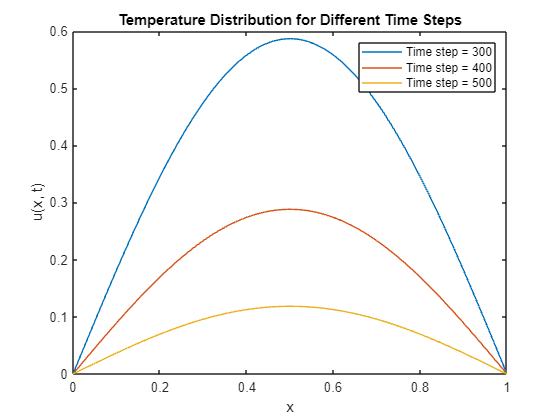

% Parameters
L = 1;          % Length of the rod
n = 50;         % Number of spatial grid points
dx = L / n;     % Spatial step size
F = 0.9;        % Safety factor
dt = F * (dx^2) / 2;  % Time step

% Initialize grid
x = linspace(0, L, n+1);
u = sin(pi * x);  % Initial condition

% Parameters
L = 1;          % Length of the rod
n = 50;         % Number of spatial grid points
dx = L / n;     % Spatial step size
F = 0.9;        % Safety factor

% Initialize grid
x = linspace(0, L, n+1);
T0 = sin(pi * x);  % Initial condition

% Time-stepping loop
time_steps = [300, 400, 500];
figure;

for k = 1:length(time_steps)
    nt = time_steps(k);
    dt = F * (dx^2) / 2;
   
    for j = 1:nt
        T1 = zeros(size(T0));
        for i = 2:n
            T1(i) = T0(i) + dt * (T0(i+1) - 2*T0(i) + T0(i-1)) / dx^2;
        end
        T0 = T1;
    end
   
    plot(x, T1, 'DisplayName', ['Time step = ' num2str(nt)]);
    hold on;
end

title('Temperature Distribution for Different Time Steps');
xlabel('x');
ylabel('u(x, t)');
legend;
hold off;